# Спектральный анализ в MATLAB

Чтение аудиофайла - запись колебания струны гитары (220 Гц).

[x,fs] = audioread('A220.mp3');
% sound(x,fs);
x = x(1:2^15);

Установка параметров - количества отсчётов входного вектора, длины БПФ, отсчётов перекрытия спектра, типа оконной функции:

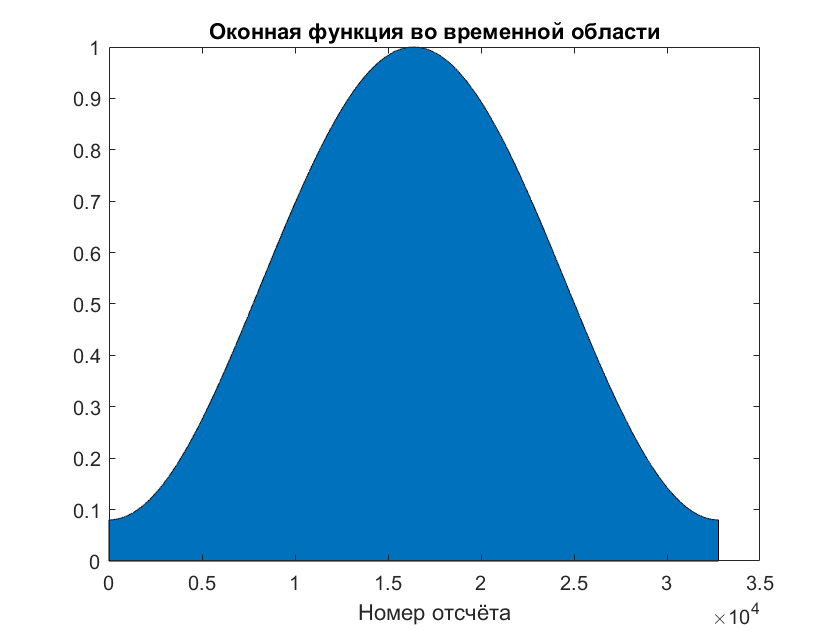

nwindow = 2^15;         % длина входного вектора (входного окна)
nFFT = 2^15;            % длина БПФ (Nfft)
noverlap = 0;           % количество отсчётов перекрытия
% win = ones(nwindow,1);
win = hamming(nwindow); % тип оконной функции
area(win);
title('Оконная функция во временной области');
xlabel('Номер отсчёта');

Оценка спектральной плотности мощности сигнала функцией **pwelch**:

[pxx,f] = pwelch(x,win,noverlap,nFFT,fs);
area(f,pxx);
title('Спектральная плотность мощности сигнала');
xlabel('Частота (Гц)');
xlim([0 1200]);
RBW = fs/nFFT;
disp(['Разрешение по чаcтоте:   ' num2str(RBW) ' Гц']);

Разрешение по чаcтоте:   1.3458 Гц


Нахождение максимумов спектра:

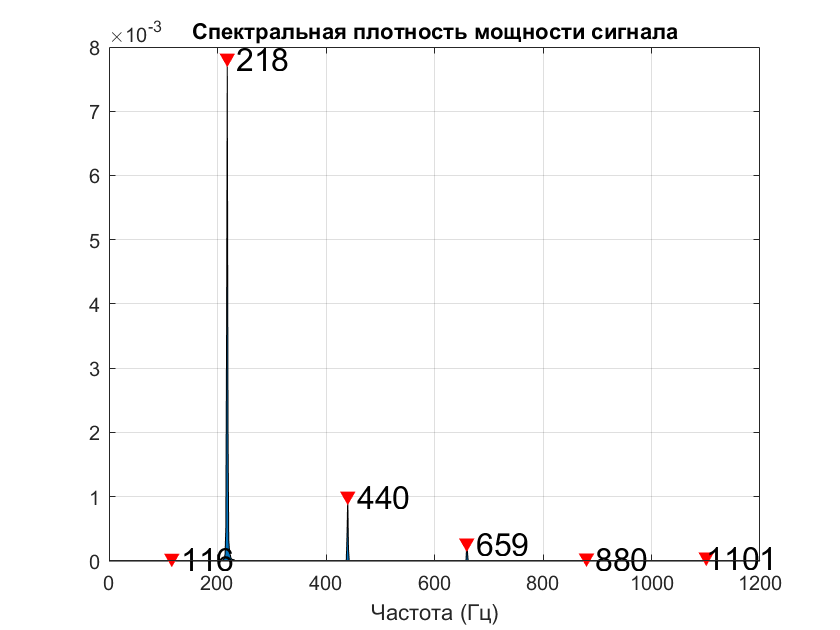

[~,locs] = findpeaks(pxx,'MinPeakHeight',1e-5,'MinPeakDistance',nFFT/500);
Fpeaks = f(locs);                         
hold on;
plot(Fpeaks,pxx(locs),'rv','MarkerFaceColor','r');
cellpeaks = cellstr(num2str(round(Fpeaks)));
text(Fpeaks,pxx(locs),cellpeaks,'FontSize',16);
grid on;
hold off;